## **Convert raw signal data into an ensamble datastore files**

- In the directory, "files" are five .mat files.

- Each of these file is a 1*1 struct with 8 fields corresponding to different load levels.

- Each level a 1*2 struct having data from 2 experiments each with 12 fields corresponsing to electrical and mechanical quantities of the AC Induction motor

- The following code block extracts the experimental data taking into consideration their sampling frequency.

- Moreover, the extracted data is stored in a separate folder in this directory, "data_files"

**Load levels used in the original experimental setup**

[12.5, 25, 37.5, 50, 62.5, 75, 87.5].*0.01.*4.1 %the array represents percentage of the full load

ans =     0.5125    1.0250    1.5375    2.0500    2.5625    3.0750    3.5875



addpath('C:\Users\mesfink\Documents\pred_maint\data');
numExperiments = 2;

folder = 'data_files';
if ~exist(folder, 'dir')
    mkdir(folder);
end

% Names of the original data files restored from the zip archive.
files = [ ...
  "struct_rs_R1.mat", ...
  "struct_r1b_R1.mat", ...
  "struct_r2b_R1.mat", ...
  "struct_r3b_R1.mat", ...
  "struct_r4b_R1.mat", ...
  ];

% Rotor conditions (that is, number of broken bars) corresponding to original data files.
    health = [
      "healthy", ...
      "broken_bar_1", ...
      "broken_bar_2", ...
      "broken_bar_3", ...
      "broken_bar_4", ...
      ];

Fs_vib = 7600; % Sampling frequency of vibration signals in Hz.
Fs_elec = 50000;  % Sampling frequency of electrical signals in Hz.

for i = 1:numel(health)
  fprintf('Processing data file %s\n', files(i))

  % Load the original data set stored as a struct.
  S = load(files(i))
  fields = fieldnames(S);
  dataset = S.(fields{1});

  loadLevels = fieldnames(dataset);
  % Iterate over load (torque) levels in each data set.
  for j = 1:numel(loadLevels)
    experiments = dataset.(loadLevels{j});
    data = struct;

    % Iterate over the given number of experiments for each load level.
    for k = 1:numExperiments
      signalNames = fieldnames(experiments(k));
      % Iterate over the signals in each experimental data set.
      for l = 1:numel(signalNames)
        % Experimental (electrical and vibration) data
        data.(signalNames{l}) = experiments(k).(signalNames{l});
      end

      % Operating conditions
      data.Health = health(i);
      data.Load = string(loadLevels{j});

      % Constant parameters
      data.Fs_vib = Fs_vib;
      data.Fs_elec = Fs_elec;

      % Save memberwise data.
      name = sprintf('rotor%db_%s_experiment%02d',  i-1, loadLevels{j}, k);
      fprintf('\tCreating the member data file %s.mat\n', name)
      filename = fullfile(pwd, folder, name);
      save(filename, '-v7.3', '-struct', 'data'); % Save fields as individual variables.
    end
  end
end

Processing data file struct_rs_R1.mat


S = struct with fields:
    rs: [1×1 struct]


	Creating the member data file rotor0b_torque05_experiment01.mat
	Creating the member data file rotor0b_torque05_experiment02.mat
	Creating the member data file rotor0b_torque10_experiment01.mat
	Creating the member data file rotor0b_torque10_experiment02.mat
	Creating the member data file rotor0b_torque15_experiment01.mat
	Creating the member data file rotor0b_torque15_experiment02.mat
	Creating the member data file rotor0b_torque20_experiment01.mat
	Creating the member data file rotor0b_torque20_experiment02.mat
	Creating the member data file rotor0b_torque25_experiment01.mat
	Creating the member data file rotor0b_torque25_experiment02.mat
	Creating the member data file rotor0b_torque30_experiment01.mat
	Creating the member data file rotor0b_torque30_experiment02.mat
	Creating the member data file rotor0b_torque35_experiment01.mat
	Creating the member data file rotor0b_torque35_experiment02.mat
	Creating the member data file rotor0b_torque40_experiment01.mat
	Creating the member data

Processing data file struct_r1b_R1.mat


S = struct with fields:
    r1b: [1×1 struct]


	Creating the member data file rotor1b_torque05_experiment01.mat
	Creating the member data file rotor1b_torque05_experiment02.mat
	Creating the member data file rotor1b_torque10_experiment01.mat
	Creating the member data file rotor1b_torque10_experiment02.mat
	Creating the member data file rotor1b_torque15_experiment01.mat
	Creating the member data file rotor1b_torque15_experiment02.mat
	Creating the member data file rotor1b_torque20_experiment01.mat
	Creating the member data file rotor1b_torque20_experiment02.mat
	Creating the member data file rotor1b_torque25_experiment01.mat
	Creating the member data file rotor1b_torque25_experiment02.mat
	Creating the member data file rotor1b_torque30_experiment01.mat
	Creating the member data file rotor1b_torque30_experiment02.mat
	Creating the member data file rotor1b_torque35_experiment01.mat
	Creating the member data file rotor1b_torque35_experiment02.mat
	Creating the member data file rotor1b_torque40_experiment01.mat
	Creating the member data

Processing data file struct_r2b_R1.mat


S = struct with fields:
    r2b: [1×1 struct]


	Creating the member data file rotor2b_torque05_experiment01.mat
	Creating the member data file rotor2b_torque05_experiment02.mat
	Creating the member data file rotor2b_torque10_experiment01.mat
	Creating the member data file rotor2b_torque10_experiment02.mat
	Creating the member data file rotor2b_torque15_experiment01.mat
	Creating the member data file rotor2b_torque15_experiment02.mat
	Creating the member data file rotor2b_torque20_experiment01.mat
	Creating the member data file rotor2b_torque20_experiment02.mat
	Creating the member data file rotor2b_torque25_experiment01.mat
	Creating the member data file rotor2b_torque25_experiment02.mat
	Creating the member data file rotor2b_torque30_experiment01.mat
	Creating the member data file rotor2b_torque30_experiment02.mat
	Creating the member data file rotor2b_torque35_experiment01.mat
	Creating the member data file rotor2b_torque35_experiment02.mat
	Creating the member data file rotor2b_torque40_experiment01.mat
	Creating the member data

Processing data file struct_r3b_R1.mat


S = struct with fields:
    r3b: [1×1 struct]


	Creating the member data file rotor3b_torque05_experiment01.mat
	Creating the member data file rotor3b_torque05_experiment02.mat
	Creating the member data file rotor3b_torque10_experiment01.mat
	Creating the member data file rotor3b_torque10_experiment02.mat
	Creating the member data file rotor3b_torque15_experiment01.mat
	Creating the member data file rotor3b_torque15_experiment02.mat
	Creating the member data file rotor3b_torque20_experiment01.mat
	Creating the member data file rotor3b_torque20_experiment02.mat
	Creating the member data file rotor3b_torque25_experiment01.mat
	Creating the member data file rotor3b_torque25_experiment02.mat
	Creating the member data file rotor3b_torque30_experiment01.mat
	Creating the member data file rotor3b_torque30_experiment02.mat
	Creating the member data file rotor3b_torque35_experiment01.mat
	Creating the member data file rotor3b_torque35_experiment02.mat
	Creating the member data file rotor3b_torque40_experiment01.mat
	Creating the member data

Processing data file struct_r4b_R1.mat


S = struct with fields:
    r4b: [1×1 struct]


	Creating the member data file rotor4b_torque05_experiment01.mat
	Creating the member data file rotor4b_torque05_experiment02.mat
	Creating the member data file rotor4b_torque10_experiment01.mat
	Creating the member data file rotor4b_torque10_experiment02.mat
	Creating the member data file rotor4b_torque15_experiment01.mat
	Creating the member data file rotor4b_torque15_experiment02.mat
	Creating the member data file rotor4b_torque20_experiment01.mat
	Creating the member data file rotor4b_torque20_experiment02.mat
	Creating the member data file rotor4b_torque25_experiment01.mat
	Creating the member data file rotor4b_torque25_experiment02.mat
	Creating the member data file rotor4b_torque30_experiment01.mat
	Creating the member data file rotor4b_torque30_experiment02.mat
	Creating the member data file rotor4b_torque35_experiment01.mat
	Creating the member data file rotor4b_torque35_experiment02.mat
	Creating the member data file rotor4b_torque40_experiment01.mat
	Creating the member data

## Declare methods and properties of ***file ensamble datastore***

- Read function property: Useful to manipulate the extracted data before feeding it into the ensamble datastore. The modified data can further be used as synthetic data variables 

- Declare which variables are condition variable. In this project, the condition variables are the health status(no of rotor bars broken) and the load level.


location = fullfile(pwd, folder);
ens = fileEnsembleDatastore(location, '.mat');

ens.ReadFcn = @readMemberData; %the code of this function is included in this directory
ens.WriteToMemberFcn = @writeMemberData;  % or @writeNewData if renamed appropriately

ens.DataVariables = [...
  "Va"; "Vb"; "Vc"; "Ia"; "Ib"; "Ic"; ...
  "Vib_acpi"; "Vib_carc"; "Vib_acpe"; "Vib_axial"; "Vib_base"; "Trigger"];
ens.ConditionVariables = ["Health" + ...
    ""; "Load"];
ens.SelectedVariables = ["Ia"; "Vib_acpi"; "Health"; "Load"];

% Add synthetic signals and spectra generated directly in the readMemberData
% function.
ens.DataVariables = [ens.DataVariables; "Vib_acpi_env"; "Ia_env_ps"];
ens.SelectedVariables = [ens.SelectedVariables; "Vib_acpi_env"; "Ia_env_ps"];


## Visualization for clearer examination of the data and its modification by @readfcn

**Extracted electrical and mechanical signals**

sampleData = load(filename);% single struct with 16 fields as generated by the above code
fields = fieldnames(sampleData);% a cell(list) containing the names of each signal 
sampleData

sampleData = struct with fields:
      Fs_elec: 50000
       Fs_vib: 7600
       Health: "broken_bar_4"
           Ia: [1001000×1 double]
           Ib: [1001000×1 double]
           Ic: [1001000×1 double]
         Load: "torque40"
      Trigger: [149759×1 double]
           Va: [1001000×1 double]
           Vb: [1001000×1 double]
           Vc: [1001000×1 double]
     Vib_acpe: [149759×1 double]
     Vib_acpi: [149759×1 double]
    Vib_axial: [149759×1 double]
     Vib_base: [149759×1 double]
     Vib_carc: [149759×1 double]


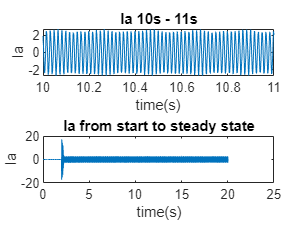

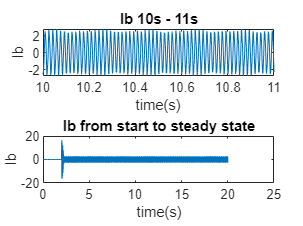

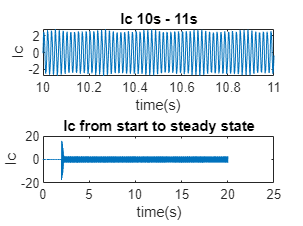

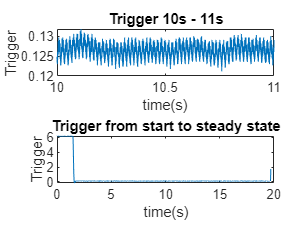

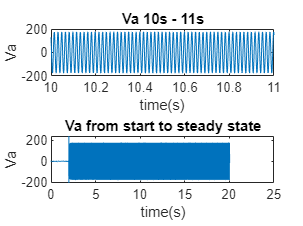

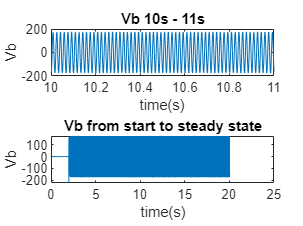

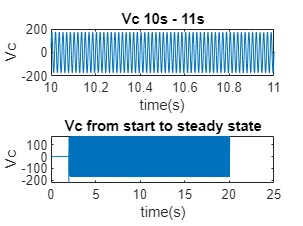

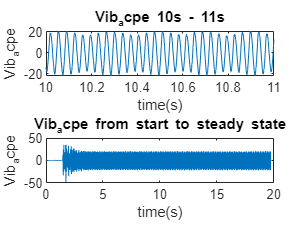


for i = 1:numel(fields) 
    signal = sampleData.(fields{i});
    if (isnumeric(signal)) & (numel(signal) > 1)
        time = 0:size(signal)-1;
        switch fields{i}           
            case {'Va', 'Vb', 'Vc', 'Ia', 'Ib', 'Ic'}
              % Electrical signals
              time = time/sampleData.(fields{1});
              des_time = find((time >= 10.0) & (time <= 11.0));
              
              figure;
              subplot(2,1,1)
              plot(time(des_time), signal(des_time))
              xlabel("time(s)")
              ylabel(fields{i})
              title(fields{i}+" 10s - 11s")
              
              subplot(2,1,2)
              plot(time, signal)
              xlabel("time(s)")
              ylabel(fields{i})
              title(fields{i}+" from start to steady state")

            case {'Vib_acpi', 'Vib_carc', 'Vib_acpe', 'Vib_axial', 'Vib_base', 'Trigger'}
              % Vibration signals
              time = time/sampleData.(fields{2});
              des_time = find((time >= 10.0) & (time <= 11.0));
              
              figure;
              subplot(2,1,1)
              plot(time(des_time), signal(des_time))
              xlabel("time(s)")
              ylabel(fields{i})
              title(fields{i}+" 10s - 11s")
              
              subplot(2,1,2)
              plot(time, signal)
              xlabel("time(s)")
              ylabel(fields{i})
              title(fields{i}+" from start to steady state")
        end
    end 
end

## Synthetic signals

- Three synthetic signals are generated [Vib_acpi_env, Ia_env, Ia_env_ps]

- Here, we will go through the generation process using just one member data

***Ia_env - Envelop of filtered phase "a" current signal***

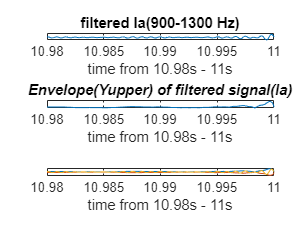

Ia_ = sampleData.Ia;
n = size(Ia_, 1);
ti = (0:n-1)' / sampleData.Fs_elec; %create a vertical array of time for the signal
I = find((ti >= 10.0) & (ti <= 11.0));% 1.0 sec of data from 10s to 11s
%create a table for the selected data
TT = timetable(Ia_(I), 'VariableNames', "Data", 'RowTimes', seconds(ti(I)));

% Envelope of band-pass filtered signal
y = bandpass(TT.Data, [900 1300], sampleData.Fs_elec);%filter signal to pass those having a frequency from 900 to 1300 Hz
yUpper = envelope(y);%use the envelop function to pinpoint the high and lows of the signal

%the following figure helps visualize both Ia(1second) and its envelop

figure();
subplot(3,1,1)
plot(ti(I(end-1000:end,1)), y(end-1000:end,1))
xlabel("time from 10.98s - 11s")
title("filtered Ia(900-1300 Hz)")

subplot(3,1,2)
plot(ti(I(end-1000:end,1)), yUpper(end-1000:end,1))
xlabel("time from 10.98s - 11s")
title("Envelope(Yupper) of filtered signal(Ia)", 'FontAngle','italic')

[yUpper_env, yLower_env] = envelope(y);
subplot(3,1,3)
plot(ti(I(end-1000:end,1)), yUpper_env(end-1000:end,1))
hold on
plot(ti(I(end-1000:end,1)), yLower_env(end-1000:end,1))
hold on
plot(ti(I(end-1000:end,1)), y(end-1000:end,1))
hold off

xlabel("time from 10.98s - 11s")
ylabel("Envelope(Ia-filtered)", 'FontAngle','italic')

***Ia_env_ps - Envelop of the spectrum of band-pass filtered Ia***

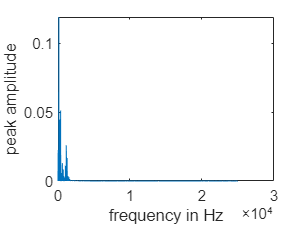


%find the envelop of the spectrum of band-pass filtered Ia
[ES,F] = envspectrum(TT, 'Method', 'hilbert', 'Band', [900 1300]);

figure;
plot(F, ES)
xlabel("frequency in Hz")
ylabel("peak amplitude")

T = read(ens)

T = 1×6 table
            Ia                  Vib_acpi            Vib_acpi_env          Ia_env_ps         Health         Load   
    ___________________    __________________    __________________    ________________    _________    __________

    {50001×1 timetable}    {7601×1 timetable}    {7601×1 timetable}    {25001×2 double}    "healthy"    "torque05"


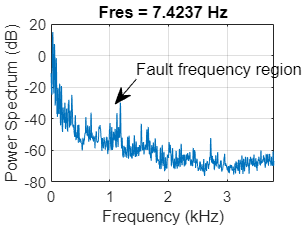


% Power spectrum of vibration signal, Vib_acpi
vib = T.Vib_acpi{1};
pspectrum(vib.Data, Fs_vib);
annotation("textarrow", [0.45 0.38], [0.65 0.54], "String", "Fault frequency region of interest")

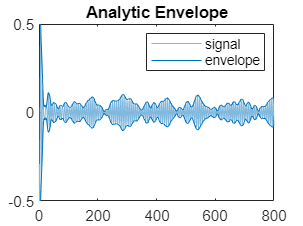

y = bandpass(vib.Data, [900 1300], Fs_vib);
envelope(y)
axis([0 800 -0.5 0.5])

T = readall(ens)

T = 80×6 table
            Ia                  Vib_acpi            Vib_acpi_env          Ia_env_ps         Health         Load   
    ___________________    __________________    __________________    ________________    _________    __________

    {50001×1 timetable}    {7601×1 timetable}    {7601×1 timetable}    {25001×2 double}    "healthy"    "torque05"
    {50001×1 timetable}    {7601×1 timetable}    {7601×1 timetable}    {25001×2 double}    "healthy"    "torque05"
    {50001×1 timetable}    {7601×1 timetable}    {7601×1 timetable}    {25001×2 double}    "healthy"    "torque10"
    {50001×1 timetable}    {7601×1 timetable}    {7601×1 timetable}    {25001×2 double}    "healthy"    "torque10"
    {50001×1 timetable}    {7601×1 timetable}    {7601×1 timetable}    {25001×2 double}   

T.Ia_env_ps{80}

ans = 	1.0e+04 *

         0    0.0000
    0.0001    0.0000
    0.0002    0.0000
    0.0003    0.0000
    0.0004    0.0000
    0.0005    0.0000
    0.0006    0.0000
    0.0007    0.0000
    0.0008    0.0000
    0.0009    0.0000


app = diagnosticFeatureDesigner;